We eliminate the guesswork for $w(0)$ and let `shoot` do the work for us.

lambda = 0.6;
phi = @(r,w,dwdr) lambda./w.^2 - dwdr./r;   
a = eps;  b = 1;    % avoid r=0 in denominator

We specify the given and unknown endpoint values.

lval = [];  lder = 0;   % w(a)=?, w'(a)=0
rval = 1;   rder = [];  % w(b)=1, w'(b)=?

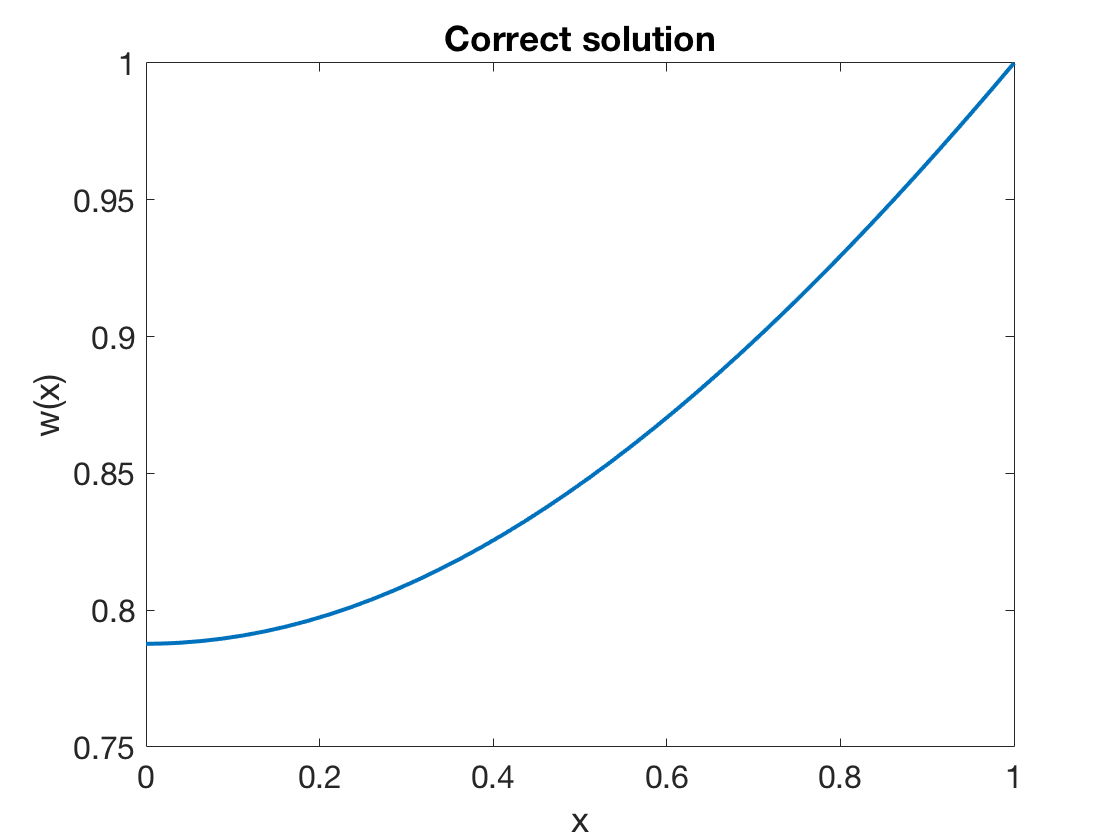

[r,w,dwdx] = shoot(phi,[a,b],lval,lder,rval,rder,0.8);
plot(r,w)
title('Correct solution')   % ignore this line
xlabel('x'), ylabel('w(x)')   % ignore this line

The value of $w$ at $r=1$, meant to be exactly one, was computed to be

format long
w(end)

ans =    0.999989011251061


The accuracy is consistent with the error tolerance used for `ode45` by `shoot`. The initial value $w(0)$ that gave this solution is

w(1)

ans =    0.787737737464385
